# 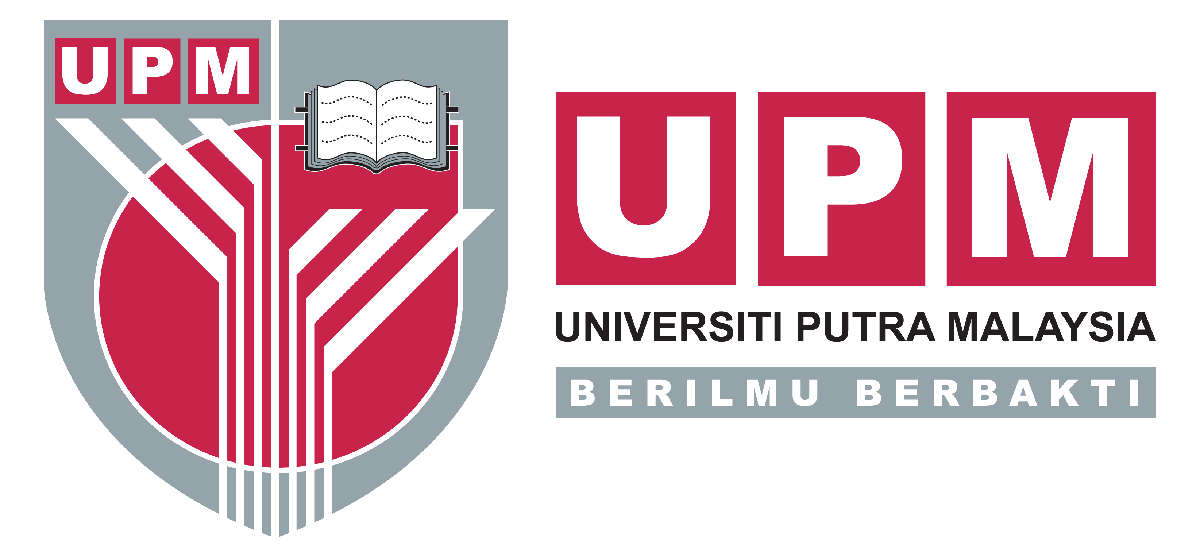

# **Classical Mechanics**

**Mini Project | Computational Physics (PHY4602) | Semester 1 2023/2024**

**Chapter: Ballistic & Air Resistance (pg. 39)**

**Group Members**

- Siti Balqis Bt Mohd Riduan (206343)

- Nursafya Melati Bt Hamidi (209060)

- Nurul Atikah Farhanah Bt Abdullah (209042)

- Syahidatul Mashitah Bt Tuah (205250)

## **Introduction **

Ballistics is the science that deals with the motion, behavior, and effects of projectiles, which are objects thrown or projected into the air. It encompasses a range of phenomena related to the flight of projectiles, including their launch, trajectory, and impact. Ballistics is crucial in various fields, such as military science, forensic science, and sports.

Air resistance, also known as drag, is a force that opposes the motion of an object through a fluid, in this case, air. When a projectile is launched, it encounters air resistance, which can significantly influence its trajectory and velocity. Understanding air resistance is essential in ballistics because it affects the performance of projectiles, including bullets, missiles, and even sports equipment like soccer balls.

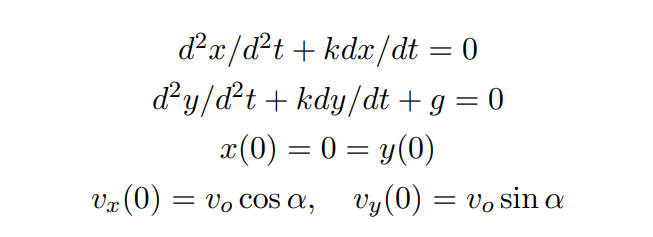

The x coordinate is horizontal and y is the vertical position. The constant k specifies the velocity dependent air resistance. The initial angle of the projectile is α.

## Initialization

clear;
help cm_ballis_sym;

 
  Program to compute the trajectory of a projectile with air resistance



## Symbolic Variables

Declare the variables used for this subchapter

syms g k x y t vo alf ax ay p q pp qq ttt;
% eqs of motion of projectile falling under gravity
%
fprintf('Projectile Motion, Air Resistance  - Acceleration = k*dy/dt \n');

Projectile Motion, Air Resistance  - Acceleration = k*dy/dt 


fprintf(' Air resistance k (sec^-1), Initial Angle/Velocity alf, vo -  x(t) and y(t) \n');

 Air resistance k (sec^-1), Initial Angle/Velocity alf, vo -  x(t) and y(t) 


## Equations of Motion and Display Results

This line of code solves the differential equations representing the projectile's motion with and without air resistance in both x and y directions. And the prints the information about the projectile motion and displays the equations of motion with and without air resistance.

p = dsolve('D2x+k*Dx=0','Dx(0)=vo*cos(alf)','x(0)=0');

pp = dsolve('D2x=0','Dx(0)=vo*cos(alf)','x(0)=0');

pretty(p)

vo cos(alf)   vo exp(-k t) cos(alf)
----------- - ---------------------
     k                  k



fprintf('x(t) With No Resistance \n')

x(t) With No Resistance 


pretty(pp)

t vo cos(alf)



%
q = dsolve('D2y+k*Dy+g=0','Dy(0)=vo*sin(alf)','y(0)=0');

qq = dsolve('D2y+g=0','Dy(0)=vo*sin(alf)','y(0)=0');

pretty(q)

g + k vo sin(alf)   g t   exp(-k t) (g + k vo sin(alf))
----------------- - --- - -----------------------------
         2           k                   2
        k                               k



fprintf('y(t) With No Resistance \n')

y(t) With No Resistance 


pretty(qq)

                   2
                g t
t vo sin(alf) - ----
                  2



## Terminal Velocity

Calculates and displays the y-velocity with air resistance. We will also defines gravitational acceleration and air resistance parameters and initializing loop control and figure indexing variables.

fprintf('y Velocity With Air Resistance \n');%

y Velocity With Air Resistance 


ttt = diff(q,t);
pretty(ttt)

exp(-k t) (g + k vo sin(alf))   g
----------------------------- - -
              k                 k



%
gg = 9.8; % MKS units m/sec^2
kkk = 0.1;  % has 1/T units
%
irun = 1;
iloop = 0;

## Main Simulation Loop

Allows the user to pick different initial velocity and angle combinations.

Projectile Motion, Air Resistance  - Initial Velocity vo 


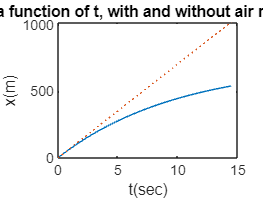

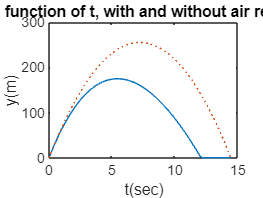

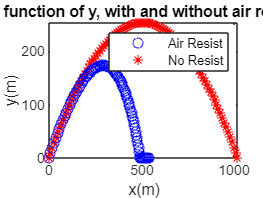

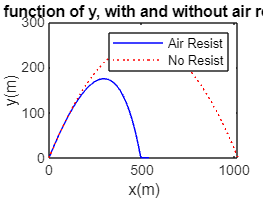

while irun > 0
    kk = menu('Pick Another Initial Velocity and Angle?','Yes','No');
    if kk == 2
        irun = -1;
        break
    end
    if kk == 1
        %
        syms g k x y t vo alf ax ay p q pp qq ttt
        fprintf('Projectile Motion, Air Resistance  - Initial Velocity vo \n');
        %
        voo = input('Enter Initial Projectile Velocity (m/sec): ');
        %
        aa = input('Enter Initial Projectile Angle (deg): ');
        %
        aa = (aa .*2 .*pi) ./360.0;
        %
        % pick max time from no resistance case
        %
        tt = linspace(0, (2.0 .*voo .*sin(aa)) ./gg);
        %
        p = dsolve('D2x+k*Dx=0','Dx(0)=vo*cos(alf)','x(0)=0');
        pp = dsolve('D2x=0','Dx(0)=vo*cos(alf)','x(0)=0');
        q = dsolve('D2y+k*Dy+g=0','Dy(0)=vo*sin(alf)','y(0)=0');
        qq = dsolve('D2y+g=0','Dy(0)=vo*sin(alf)','y(0)=0');
        alf = aa;
        %
        g = gg;
        k = kkk;
        vo = voo;
        %
        for i=1:100
            t = tt(i);
            xxx(i) = eval(p); % resistance dxdt
            yyy(i) = eval(q); % resistance dydt
            if yyy(i) < 0;
                yyy(i) = 0;
            end
        end
        % 
        for i=1:100
            t = tt(i);
            Xxx(i) = eval(pp); % free fall
            Yyy(i) = eval(qq);
            if Yyy(i) < 0
                Yyy(i) = 0;
            end
        end
        %
        iloop = iloop + 1;
        %
        figure(iloop)
        plot(tt,xxx,tt,Xxx,':')
        title('x as a function of t, with and without air resistance')
        xlabel('t(sec)')
        ylabel('x(m)')
        %
        iloop = iloop + 1;
        figure(iloop)
        plot(tt,yyy,tt,Yyy,':')
        title('y as a function of t, with and without air resistance')
        xlabel('t(sec)')
        ylabel('y(m)')
        %
        iloop = iloop + 1;
        figure(iloop)
        jj = length(xxx);
        xmax = max(Xxx);
        ymax = max(Yyy);
        for i = 1:jj
           plot(xxx(i),yyy(i),'bo',Xxx(i),Yyy(i),'r*')
           title('x as a function of y, with and without air resistance')
           xlabel('x(m)')
           ylabel('y(m)')
           pause(0.1)
           axis([0, xmax, 0, ymax])
           legend('Air Resist','No Resist')
           hold on
        end
        hold off
        iloop = iloop + 1;
        figure(iloop)
        plot(xxx,yyy,'-b',Xxx,Yyy,'r:')
        title('x as a function of y, with and without air resistance')
        xlabel('x(m)')
        ylabel('y(m)')
        legend('Air Resist','No Resist')
        %
    end
end

## Conclusion

This MATLAB code simulates the trajectory of a projectile considering air resistance, providing a comprehensive analysis of its motion. The program uses symbolic mathematics to solve the equations of motion for a projectile subject to air resistance, considering both horizontal and vertical components. It compares the results to the case without air resistance, demonstrating the impact of aerodynamic forces on the trajectory. The user can input initial velocity and angle values to explore different scenarios. The code further calculates and displays the terminal velocity with air resistance. The simulation results are visualized through plots depicting the projectile's position over time, emphasizing the differences between cases with and without air resistance. Overall, this code serves as a valuable tool for understanding and visualizing the effects of air resistance on projectile motion, providing insights into real-world scenarios and aiding in the optimization of projectile design and performance.